# Characterize Motor Inertia and Friction using Simulink Design Optimization

## Description

Goal of this exercise is to estimate value of Motor Rotor + Disk Inertia and Firction Coefficients using data captured from Coastdown Experiment. We will use Parameter Estimator App from [Simulink Design Optimization](https://www.mathworks.com/products/sl-design-optimization.html#response) to estimate values of following parameters in data dictionary *SGKitPlantData.sldd*: 

- **discInertia**

- **pmsmInertia**

- **pmsmCoulombFrictionTorque** 

- **pmsmViscousFrictionCoefficient**

First step in parameter estimation is to get experiment data. We can either run a new coastdown experiment using Speedgoat hardware setup or use data from past experiment, saved in *CoastDownExperimentData_SG.mat*. Next we compare experiment results with simulation result. Here we notice that, in comparison to experiment, the motor takes longer time to come to complete halt in desktop simulation. This mismatch is a result of poor initial guess for Rotor and Disk Inertia and Friction Coefficients. To minimize this error between simulation and experimental data, we will use* spetool()* from Simulink Design Optimization to estimate values of these parameter set. 

This project contains a pre-built example session “CoastDown_SPE_Session” to help you get started with parameter estimation. To learn more about Parameter Estimator App, please refer to this MathWorks [resource page](https://www.mathworks.com/products/sl-design-optimization.html#parameter). 

## Select Source of Experiment Data

User_Choice = "Live Experiment";
ExperimentType = "ClosedLoop_CoastdownTest";

### Execute Coastdown Experiment

if User_Choice == "Live Experiment"
    % Open TestHarness and Setup Coast Down Experiment
    mdl = 'FieldOrientedController_RCP';
    open_system(mdl);
    switchConfig('RCP');
    
    % Select Signal Editor Experiement
    set_param([mdl,'/enManualTestInputs'],'Value','0'); % Select SignalEditor_Experiments as Test Inputs
    set_param([mdl,'/SignalEditor_Experiments'],'ActiveScenario',ExperimentType); % Select Experiment
    
    % Build Model for Speedgoat Real-Time Target
    rtwbuild(mdl); % Build Model
    
    % Run Experiment
    tg = slrealtime;
    proj = matlab.project.rootProject;
    cd(proj.SimulinkCodeGenFolder); %move to build folder
    load(tg,mdl);
    tg.setStopTime(5)    
    tg.start; pause(5);
    
    % Plot Results
    expRun = Simulink.sdi.Run.getLatest;
    expRun.Name = ['CoastdownExp - ' char(expRun.DateCreated)];
    sigExp = getSignalsByName(expRun,'rotorVelocityCopy');
    Simulink.sdi.setSubPlotLayout(1,1);
    sigExp.Checked = true; % Mark Signal for Plotting
    Simulink.sdi.view % Open Simulation Data Inspector UI
    
    close_system(mdl,0); % Close RCP TestHarness Model 

### Load Data from Past Experiment

% else
%     prj = currentProject;
%     %load([prj.RootFolder{1},'\Data\CoastDownExperimentData.mat']);
%     load([prj.RootFolder{1},'\Data\CoastDownExperimentData_SG.mat']);
%     expRun = Simulink.sdi.Run.create;
%     expRun.Name = 'CoastdownExp_Recorded';
%     expRun.add('vars',data);
%     sigExp = getSignalsByName(expRun,'rotorVelocity');
%     sigExp.Checked = true;
%     Simulink.sdi.view
end

## Compare Experiment Result with Desktop Simulation 

mdl = 'FieldOrientedController_MIL';
open_system(mdl);
switchConfig('MIL');
%switchMotorKit('SG_Inverter_RCP_Kit');

% Select Configuration which is not a Configuration Reference. 
% Simulink Design Optimization does not work with Configuration Reference
setActiveConfigSet(mdl,'Sim1'); 

### Select Signal Editor Experiement 

set_param([mdl,'/enManualTestInputs'],'Value','0'); % Select SignalEditor_Experiments as Test Inputs 
set_param([mdl,'/SignalEditor_Experiments'],'ActiveScenario',ExperimentType); % Select Experiment

### Restore Initial Inertia and Friction Coefficient Values

%Initial Inertia and Friction Coefficient Values
dd=Simulink.data.dictionary.open('SGKitPlantData.sldd');
%Known Inertia and Friction Values 
% discInertia = 2.5e-5;
% pmsmInertia = 8.35e-5;
% pmsmBreakawayFrictionTorque = 0.02;
% pmsmBreakawayFrictionVelocity = 0.01;
% pmsmCoulombFrictionTorque = 6.5e-3
% pmsmViscousFrictionCoefficient = 5.3e-05;

% setValue(getEntry(getSection(dd,'Design Data'),'pmsmInertia'),8.35e-05);
setValue(getEntry(getSection(dd,'Design Data'),'discInertia'),2.5e-5);
setValue(getEntry(getSection(dd,'Design Data'),'pmsmBreakawayFrictionTorque'),0.02);
setValue(getEntry(getSection(dd,'Design Data'),'pmsmBreakawayFrictionVelocity'),0.01);
setValue(getEntry(getSection(dd,'Design Data'),'pmsmCoulombFrictionTorque'),5.5e-3);
setValue(getEntry(getSection(dd,'Design Data'),'pmsmViscousFrictionCoefficient'),4.35e-5);

% Simulate Model
sim(mdl,'StopTime','5');

### View and Compare Data in Simulation Data Inspector

desktopRun = Simulink.sdi.Run.getLatest;
desktopRun.Name = ['Coastdown Sim - ' char(desktopRun.DateCreated)];
sigSim = getSignalsByName(desktopRun,'rotorVelocity');
sigSim.Checked = true; % Mark Signal for Plotting
Simulink.sdi.view; % Open Simulation Data Inspector 

## Estimate Disc Inertia and Viscous Friction Coefficient using "spetool"

### Watch Video of Parameter Estimation

winopen('PMSM_ParamEstimation.mp4');

### Open Parameter Estimator App

%spetool('CoastDown_SPE_Session');
spetool('FieldOrientedController_MIL_spesession');


### Coastdown response before parameter estimation 

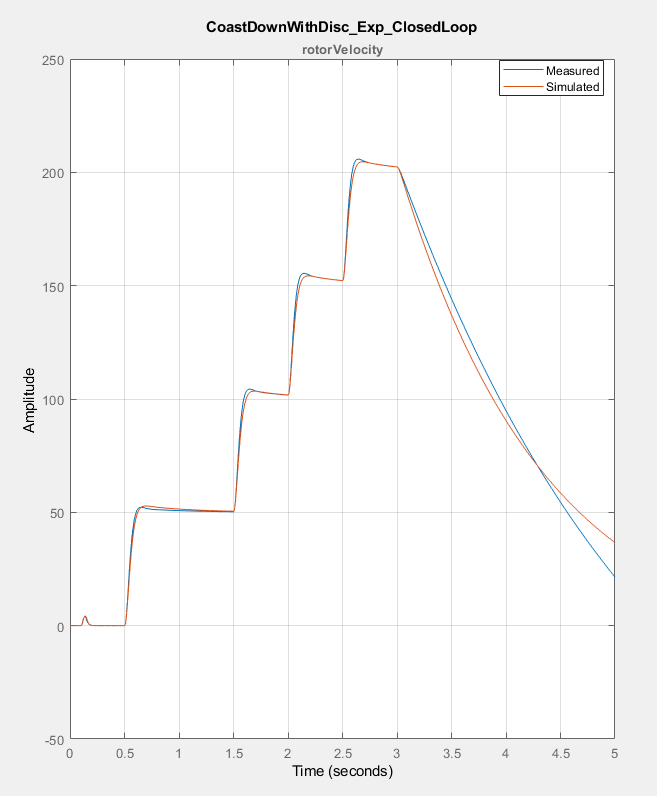            

### Coastdown response after parameter estimation 

            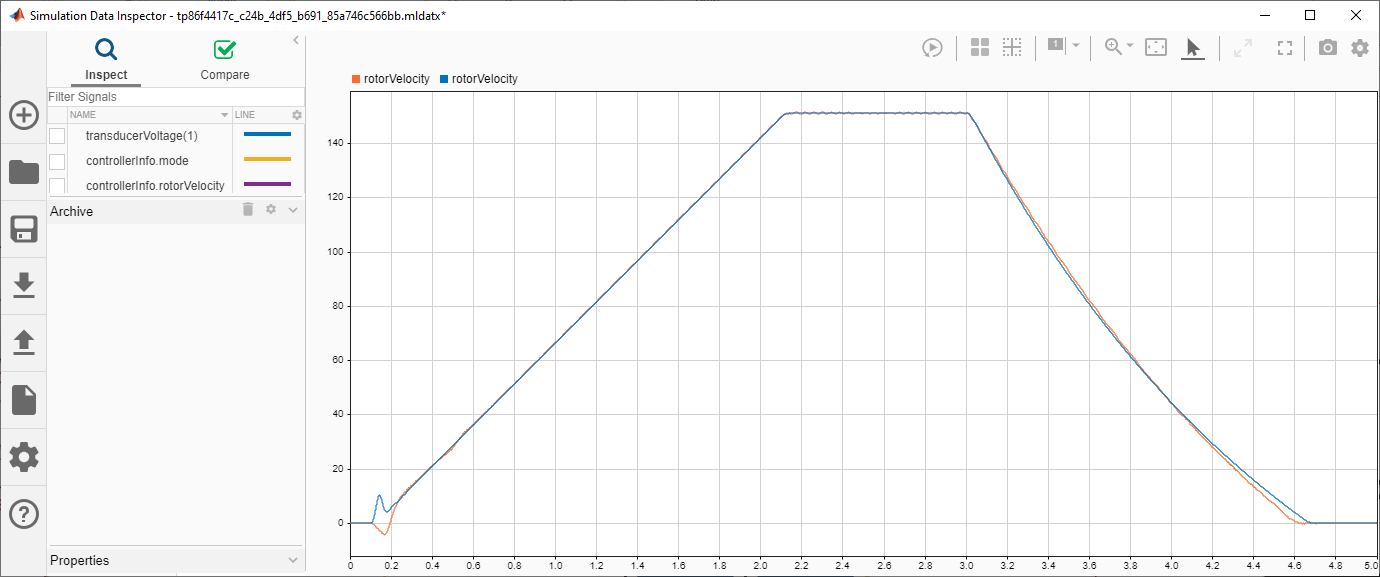

### Estimated Parameters

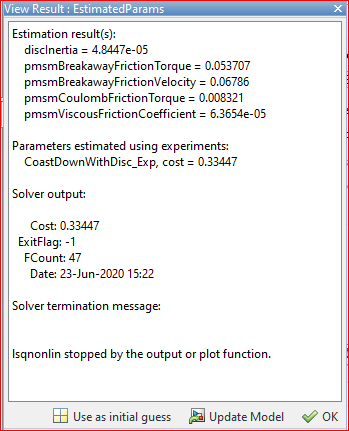

## **Restore Data Dictionary**

switchConfig('MIL'); % Reset Configuration
dd.discardChanges;
clear mdl tg expRun desktopRun sigExp sigSim dd data prj